% =========================================================================
% 04 ROBOGUIDE ÖSSZEVETÉS: a RoboGuide-futások kiértékelése
% =========================================================================
% MIT CSINÁL?
%   A RoboGuide-ban lefuttatott programok LOG_ALL logjaiból kiszámolja
%   ugyanazt a költséget, amelyet a GA becsült, így a becsült és a
%   RoboGuide-ban mért javulás közvetlenül összevethető.
%
%   Futások (04_roboguide_osszevetes\roboguide_log\, cfg.file.log_*):
%     alap.CSV  = ref, a 02_ga_durva\ls\ALAP_L.LS futása (kötelező)
%     opt1.CSV  = a 02_ga_durva\ls\OPT1_L.LS futása (1. kör), ha megvan
%     opt2.CSV  = a 03_kor2_finom\ls\OPT2_L.LS futása (2. kör), ha megvan
%   A logok UF 0 / UT 3 mellett készüljenek, a kör középpontja a
%   cfg.cella.nullpont (X, Y), ebből számoljuk a pályaszöget.
%
%   A költség ugyanaz, mint a GA-ban (kozos\config.m és kozos\lib\koltseg.m):
%   lambda = cfg.cost.lambda, a csuklók súlya 'korlat' normálásnál a mért
%   csuklókorlátokból (cfg.cost.lim), az osztók a ref (Alap) futásból,
%   így a ref költsége 1.
%
%   A fő kiértékelés ívhossz szerinti (s = R*th), mint a GA-ban. A mért
%   csuklószögeket 5°-os egyenletes pályaszög-rácsra mintavételezzük
%   (ugyanannyi pont, mint a GA 72 kiértékelő pontja), és ebből számoljuk a
%       dq/ds [°/mm],  d2q/ds2 [°/mm^2],  d3q/ds3 [°/mm^3]
%   deriváltakat. A végén (kozos\lib\ido_ivhossz_vizsgalat.m) ugyanezt idő
%   szerint is kiszámolja (dq/dt, d2q/dt2, d3q/dt3 a log Time_s oszlopából),
%   és megnézi a két módszer egyezését (költség, pontonkénti és
%   szektoronkénti korreláció, skálázás v^k-val).
%
% ELŐTTE:  a RoboGuide-futások logjai a roboguide_log mappában; az
%          elméleti összevetéshez a 02 és 03 lépés eredményei
% BEMENET: roboguide_log nevu mappat letrehozni, es belerakni a futtatasi
% csvket, alap.csv, opt1.csv es opt2.csv neven
% KIMENET: 04_roboguide_osszevetes\eredmenyek_korlat\  (CSV + PNG)
%   osszeg_csuklonkent.csv, pontonkent_<futás>.csv, szektorok.csv,
%   hozzajarulas_csuklonkent.csv, ido_vs_ivhossz_*.csv, futasok.txt,
%   m_1..m_8_*.png
% =========================================================================
clear; clc;
%% 0. ÚTVONALAK
% A projekt gyökere az a mappa, amelyben a kozos\config.m van. A futó Live
% Script helyét a matlab.desktop.editor.getActiveFilename adja meg; ha ez
% nem érhető el, a MATLAB aktuális mappájából indulunk. Innen legfeljebb
% három szintet lépünk felfelé, amíg a kozos\config.m meg nem lesz. Így a
% teljes mappa bárhová másolható, abszolút elérési utat nem kell átírni.
gyoker = '';
try, gyoker = fileparts(matlab.desktop.editor.getActiveFilename); catch, end
jeloltek = {gyoker, pwd};
for c = 1:numel(jeloltek)
    gyoker = jeloltek{c};
    for i = 1:3
        if isempty(gyoker) || isfile(fullfile(gyoker, 'kozos', 'config.m')), break; end
        gyoker = fileparts(gyoker);
    end
    if ~isempty(gyoker) && isfile(fullfile(gyoker, 'kozos', 'config.m')), break; end
end
assert(~isempty(gyoker) && isfile(fullfile(gyoker, 'kozos', 'config.m')), ...
    'Nem található a kozos\config.m. Állítsd a MATLAB aktuális mappáját a szkript mappájára.');
addpath(fullfile(gyoker, 'kozos'), fullfile(gyoker, 'kozos', 'lib'));
% Ugyanaz a config, mint a GA-nál, így ugyanaz a lambda, a normálás és a kapu.
cfg = config();

%% ===== Beállítások =====
% BEÁLLÍTÁSOK: a logok mappája; a mintavétel a körön 5 fokonként (mint a GA
% 72 pontja); a kör középpontja; a szektorméret; a kimeneti mappa.
logdir  = cfg.path.log;
lepes   = 5;        % [deg] mintavétel a körön: 5° = ugyanaz, mint az elméletben (72 pont).
                    % 2°-nál a log 0.001°-os felbontása miatt a d3q/ds3 zajjá válik.
kozep   = cfg.cella.nullpont(1:2);   % kör középpontja [mm] (X, Y), kozos\config.m
szektor = 30;       % [deg]
sfx     = cfg.cost.sfx;   % '_korlat' vagy '' (config.m)
out     = fullfile(cfg.path.ossz, ['eredmenyek' sfx]);
if ~exist(out, 'dir'), mkdir(out); end

% futás neve, log, elméleti szektorfájl + eset, elméleti kulcspontok
% A futások listája: név, log fájl, az elméleti (GA-becsült) szektortábla és
% a kulcsponti becslés - hogy a mért és becsült értéket össze lehessen vetni.
F = struct('nev', {}, 'log', {}, 'elm', {}, 'elm_eset', {}, 'kp', {});
% ref = az Alap futás (ALAP_L) logja.
F(end+1) = struct('nev', 'referencia',  'log', cfg.file.log_alap, 'elm', '', 'elm_eset', NaN, 'kp', '');
% opt1 = az 1. kör eredményének futása; az elméleti (GA-becsült) értékek a
% 02_ga_durva eredményeiből (g3 szektorai, g1 kulcspontjai).
F(end+1) = struct('nev', 'opt1', 'log', cfg.file.log_opt1, ...
    'elm', fullfile(cfg.path.res_el, 'szektorok.csv'), 'elm_eset', 1, ...
    'kp', fullfile(cfg.path.res_ga, 'opt1_kulcspontok.csv'));
% opt2 = a 2. kör eredményének futása; az elméleti értékek a 03_kor2_finom
% eredményeiből (k2 szektorai és jelölt1 kulcspontjai).
F(end+1) = struct('nev', 'opt2', 'log', cfg.file.log_opt2, ...
    'elm', fullfile(cfg.k2.res, 'szektorok.csv'), 'elm_eset', 1, ...
    'kp', fullfile(cfg.k2.res, 'jelolt1_kulcspontok.csv'));

% Csak azok a futások maradnak, amelyeknek megvan a logja; az Alap kötelező.
van = arrayfun(@(f) exist(f.log, 'file') == 2, F);
assert(van(1), 'Nincs meg a ref (Alap) log: %s', F(1).log);
F = F(van);
ne = numel(F);
assert(ne >= 2, 'Legalább egy opt log kell a roboguide_log mappába (opt1.CSV / opt2.CSV): %s', logdir);
% Futásnevek és a deriváltrendek feliratai.
nev = {F.nev};
mn  = {'dq/ds', 'd^2q/ds^2', 'd^3q/ds^3'};

%% ===== Beolvasás, deriválás =====
% BEOLVASÁS ÉS DERIVÁLÁS: minden logra
for e = 1:ne
    % a log beolvasása (a kör kivágása, J4/J6 kibontása) ...
    Lg = log_beolvas(F(e).log, kozep);
    % ... és az ívhossz szerinti deriváltak 5 fokos rácson (mint a GA-ban).
    D(e) = ivhossz_derivalt(Lg, lepes, cfg.geom.radius); %#ok<SAGROW>
    % Ellenőrző kiírás: a minták száma, a szögtartomány és a mért sugár
    % (ha a sugár nem ~300 mm, rossz frame-ben futott a program).
    r = sqrt((Lg.xyz(:,1)-kozep(1)).^2 + (Lg.xyz(:,2)-kozep(2)).^2);
    bel = Lg.th >= 0 & Lg.th < 360;
    fprintf('%-5s %6d minta, %.1f..%.1f°, sugár %.3f..%.3f mm  (%s)\n', nev{e}, ...
        numel(Lg.th), Lg.th(1), Lg.th(end), min(r(bel)), max(r(bel)), F(e).log);
end

referencia   1253 minta, -10.0..367.6°, sugár 299.857..299.868 mm  (C:\Users\dozsa\OneDrive\Desktop\ATMENETIBME\5_felev\tdk\01_v10\04_roboguide_osszevetes\roboguide_log\alap.CSV)
opt1    1253 minta, -10.0..367.5°, sugár 299.857..299.864 mm  (C:\Users\dozsa\OneDrive\Desktop\ATMENETIBME\5_felev\tdk\01_v10\04_roboguide_osszevetes\roboguide_log\opt1.CSV)
opt2    1252 minta, -10.0..367.3°, sugár 299.856..299.864 mm  (C:\Users\dozsa\OneDrive\Desktop\ATMENETIBME\5_felev\tdk\01_v10\04_roboguide_osszevetes\roboguide_log\opt2.CSV)



%% ===== Költség =====
% KÖLTSÉG: a négyzetösszegek csuklónként és deriváltrendenként, ugyanúgy,
% mint a negyzetosszeg.m-ben (derivált^2 * ds összegezve).
S = zeros(3, 6, ne);
for e = 1:ne
    for k = 1:3, S(k, :, e) = sum(D(e).d{k}.^2, 1) * D(e).ds; end
end
% Az osztók a mért Alapból (ref), és ugyanaz a költségfüggvény, mint a GA-ban.
Dn = koltseg_osztok(S(:,:,1), cfg);
[J, comp] = koltseg(S, Dn, cfg);
% Normált lambda (a pályamenti felbontáshoz kell).
lam = cfg.cost.lambda / sum(cfg.cost.lambda);

% Összesítő táblázat a konzolra: költség, változás a ref-hez és az előző
% futáshoz, deriváltrendenként, és hogy teljesül-e a kapu (cfg.ref.gate_rel).
fprintf('\nÖsszköltség (ívhossz szerint, %g°-os mintavétel), kapu: %.0f%% a referenciához képest\n', ...
    lepes, 100*cfg.ref.gate_rel);


Összköltség (ívhossz szerint, 5°-os mintavétel), kapu: -25% a referenciához képest


fprintf('  futás   költség   vs ref    vs előző    dq/ds   d2q/ds2  d3q/ds3   kapu\n');

  futás   költség   vs ref    vs előző    dq/ds   d2q/ds2  d3q/ds3   kapu


for e = 1:ne
    if e == 1
        fprintf('  %-5s   %.4f\n', nev{e}, J(e));
        continue
    end
    % Kapu: átment, ha a relatív változás legalább cfg.ref.gate_rel (pl. -10%).
    if J(e)/J(1)-1 <= cfg.ref.gate_rel, kapu = 'átment'; else, kapu = 'NEM'; end
    if e > 2, ve = sprintf('%+7.1f%%', 100*(J(e)/J(e-1)-1)); else, ve = '      - '; end
    fprintf('  %-5s   %.4f   %+6.1f%%   %s   %+6.1f%%  %+6.1f%%  %+6.1f%%   %s\n', nev{e}, J(e), ...
        100*(J(e)/J(1)-1), ve, 100*(comp(:,e)./comp(:,1) - 1), kapu);
end

  referencia   1.0000


  opt1    0.5407    -45.9%         -     -30.5%   -51.5%   -48.8%   átment
  opt2    0.5394    -46.1%      -0.2%    -30.8%   -51.5%   -48.9%   átment



% Csuklónkénti változás %-ban. Ha egy csukló ref-értéke ~0 (az Alapban a J4
% szinte nem mozdul), ott a %-os változás nem értelmezhető, ezért NaN.
fprintf('\nCsuklónként, változás a referenciához képest [%%]:\n');


Csuklónként, változás a referenciához képest [%]:


for e = 2:ne
    fprintf('  %s        J1      J2      J3      J4*     J5      J6\n', nev{e});
    for k = 1:3
        pc = 100*(S(k,:,e)./S(k,:,1) - 1);  pc(S(k,:,1) < 1e-9*max(S(k,:,1))) = NaN;
        fprintf('  %-9s', mn{k}); fprintf('%+7.1f ', pc); fprintf('\n');
    end
end

  opt1        J1      J2      J3      J4*     J5      J6


  dq/ds      -24.7   -67.4   -28.7     NaN  +141.4   -98.7 
  d^2q/ds^2  -26.8   -67.5   -29.1     NaN  +131.6   -97.7 
  d^3q/ds^3  -33.3   -68.5   -30.2     NaN  +101.0   -92.7 


  opt2        J1      J2      J3      J4*     J5      J6


  dq/ds      -23.7   -67.3   -28.9     NaN  +141.3   -98.2 
  d^2q/ds^2  -25.8   -67.5   -29.3     NaN  +131.5   -97.4 
  d^3q/ds^3  -32.6   -68.6   -30.3     NaN  +100.0   -94.0 


fprintf('  * ha a ref-érték ~0, a %%-os változás NaN (a költségben a súlyát a normálás adja).\n');

  * ha a ref-érték ~0, a %-os változás NaN (a költségben a súlyát a normálás adja).



% A csuklónkénti négyzetösszegek és változások CSV-be.
T1 = [];
for e = 1:ne
    for k = 1:3
        T1 = [T1; e-1, k, S(k,:,e), 100*(S(k,:,e)./S(k,:,1)-1), comp(k,e)]; %#ok<AGROW>
    end
end
csv_iras(fullfile(out, 'osszeg_csuklonkent.csv'), ...
    [{'futas','derivalt'}, arrayfun(@(j) sprintf('S_J%d',j), 1:6, 'UniformOutput', false), ...
     arrayfun(@(j) sprintf('valt_pct_J%d',j), 1:6, 'UniformOutput', false), {'resz'}], T1);
% futasok.txt: melyik sorszám melyik futás és log (napló).
fid = fopen(fullfile(out, 'futasok.txt'), 'w');
for e = 1:ne, fprintf(fid, '%d = %s  (%s)\n', e-1, nev{e}, F(e).log); end
fclose(fid);

%% ===== Pályamenti hozzájárulás =====
% PÁLYAMENTI HOZZÁJÁRULÁS: pontonként és csuklónként mennyit ad a költséghez
% (ugyanaz a képlet, mint a lokalis_hozzajarulas.m-ben), CSV-be kiírva.
H = cell(ne, 3);
for e = 1:ne
    for k = 1:3
        H{e,k} = lam(k) * (D(e).d{k}.^2 * D(e).ds) ./ repmat(Dn(k,:), D(e).n, 1) / 6;
    end
    M = [];
    for k = 1:3
        [a, s] = sort(D(e).ang{k});
        M = [M; k*ones(size(a)) a D(e).d{k}(s,:) H{e,k}(s,:) sum(H{e,k}(s,:),2)]; %#ok<AGROW>
    end
    csv_iras(fullfile(out, sprintf('pontonkent_%s.csv', nev{e})), ...
        [{'derivalt','szog'}, arrayfun(@(j) sprintf('d_J%d',j), 1:6, 'UniformOutput', false), ...
         arrayfun(@(j) sprintf('h_J%d',j), 1:6, 'UniformOutput', false), {'h_ossz'}], M);
end

% SZEKTOROK: a hozzájárulás szektor (30) fokos szakaszokra összegezve.
ns = 360 / szektor;
sek = zeros(ne, ns, 4);
for e = 1:ne
    for k = 1:3
        idx = floor(D(e).ang{k} / szektor) + 1;
        for s = 1:ns, hh = H{e,k}(idx == s, :); sek(e, s, k) = sum(hh(:)); end
    end
    sek(e, :, 4) = sum(sek(e, :, 1:3), 3);
end
% Mért változás szektoronként a ref-hez képest [%].
valt = 100*(squeeze(sek(:,:,4)) ./ repmat(squeeze(sek(1,:,4)), ne, 1) - 1);     % ne x ns
% Elméleti (GA-becsült) változás szektoronként, ha megvan a fájlja.
elm  = NaN(ne, ns);
for e = 2:ne
    if exist(F(e).elm, 'file')
        E = csv_olvas(F(e).elm);
        x = E(E(:,1) == F(e).elm_eset, 8)';
        if numel(x) == ns, elm(e, :) = x; end
    end
end

% Szektoronkénti táblázat a konzolra: mért vs elméleti változás, és hogy a
% teljes javulás hány %-a jön az adott szektorból.
for e = 2:ne
    fprintf('\n%s szektoronként (mért, ívhossz szerint):\n', nev{e});
    if e > 2
        fprintf('  szektor     ref     %-6s  %-6s  vs ref (mért)  vs ref (elm.)  vs %s    a javulás része\n', nev{e-1}, nev{e}, nev{e-1});
    else
        fprintf('  szektor     ref     %-6s  vs ref (mért)  vs ref (elm.)  a javulás része\n', nev{e});
    end
    for s = 1:ns
        resz = 100*(sek(1,s,4) - sek(e,s,4)) / (J(1) - J(e));
        if e > 2
            fprintf('  %3d-%3d°   %.4f  %.4f  %.4f    %+7.1f%%       %+7.1f%%     %+7.1f%%     %6.1f%%\n', ...
                (s-1)*szektor, s*szektor, sek(1,s,4), sek(e-1,s,4), sek(e,s,4), valt(e,s), elm(e,s), ...
                100*(sek(e,s,4)/sek(e-1,s,4)-1), resz);
        else
            fprintf('  %3d-%3d°   %.4f  %.4f    %+7.1f%%       %+7.1f%%       %6.1f%%\n', ...
                (s-1)*szektor, s*szektor, sek(1,s,4), sek(e,s,4), valt(e,s), elm(e,s), resz);
        end
    end
    fprintf('  összesen   %.4f  %.4f  (%+.1f%% vs ref)\n', J(1), J(e), 100*(J(e)/J(1)-1));
end


opt1 szektoronként (mért, ívhossz szerint):


  szektor     ref     opt1    vs ref (mért)  vs ref (elm.)  a javulás része


    0- 30°   0.0756  0.0448      -40.7%         -39.9%          6.7%
   30- 60°   0.0748  0.0448      -40.1%         -40.2%          6.5%
   60- 90°   0.0909  0.0488      -46.3%         -46.9%          9.2%
   90-120°   0.1162  0.0639      -45.0%         -44.5%         11.4%
  120-150°   0.1141  0.0608      -46.7%         -47.3%         11.6%
  150-180°   0.0886  0.0478      -46.0%         -46.6%          8.9%
  180-210°   0.0751  0.0453      -39.7%         -39.3%          6.5%
  210-240°   0.0759  0.0438      -42.3%         -42.1%          7.0%
  240-270°   0.0768  0.0375      -51.2%         -52.0%          8.6%
  270-300°   0.0625  0.0303      -51.5%         -50.8%          7.0%
  300-330°   0.0686  0.0325      -52.6%         -53.5%          7.9%
  330-360°   0.0810  0.0403      -50.2%         -50.9%          8.9%


  összesen   1.0000  0.5407  (-45.9% vs ref)



opt2 szektoronként (mért, ívhossz szerint):


  szektor     ref     opt1    opt2    vs ref (mért)  vs ref (elm.)  vs opt1    a javulás része


    0- 30°   0.0756  0.0448  0.0445      -41.1%         -41.2%        -0.6%        6.7%
   30- 60°   0.0748  0.0448  0.0448      -40.1%         -40.5%        +0.1%        6.5%
   60- 90°   0.0909  0.0488  0.0490      -46.1%         -45.9%        +0.3%        9.1%
   90-120°   0.1162  0.0639  0.0638      -45.1%         -45.2%        -0.1%       11.4%
  120-150°   0.1141  0.0608  0.0604      -47.0%         -47.2%        -0.7%       11.6%
  150-180°   0.0886  0.0478  0.0475      -46.3%         -46.4%        -0.6%        8.9%
  180-210°   0.0751  0.0453  0.0456      -39.3%         -39.5%        +0.7%        6.4%
  210-240°   0.0759  0.0438  0.0442      -41.9%         -42.6%        +0.7%        6.9%
  240-270°   0.0768  0.0375  0.0372      -51.5%         -51.5%        -0.6%        8.6%
  270-300°   0.0625  0.0303  0.0302      -51.6%         -51.3%        -0.3%        7.0%
  300-330°   0.0686  0.0325  0.0319      -53.5%         -53.3%        -2.0%        8.0%
  330-360°   0.0810  0.0403  0.0

  összesen   1.0000  0.5394  (-46.1% vs ref)


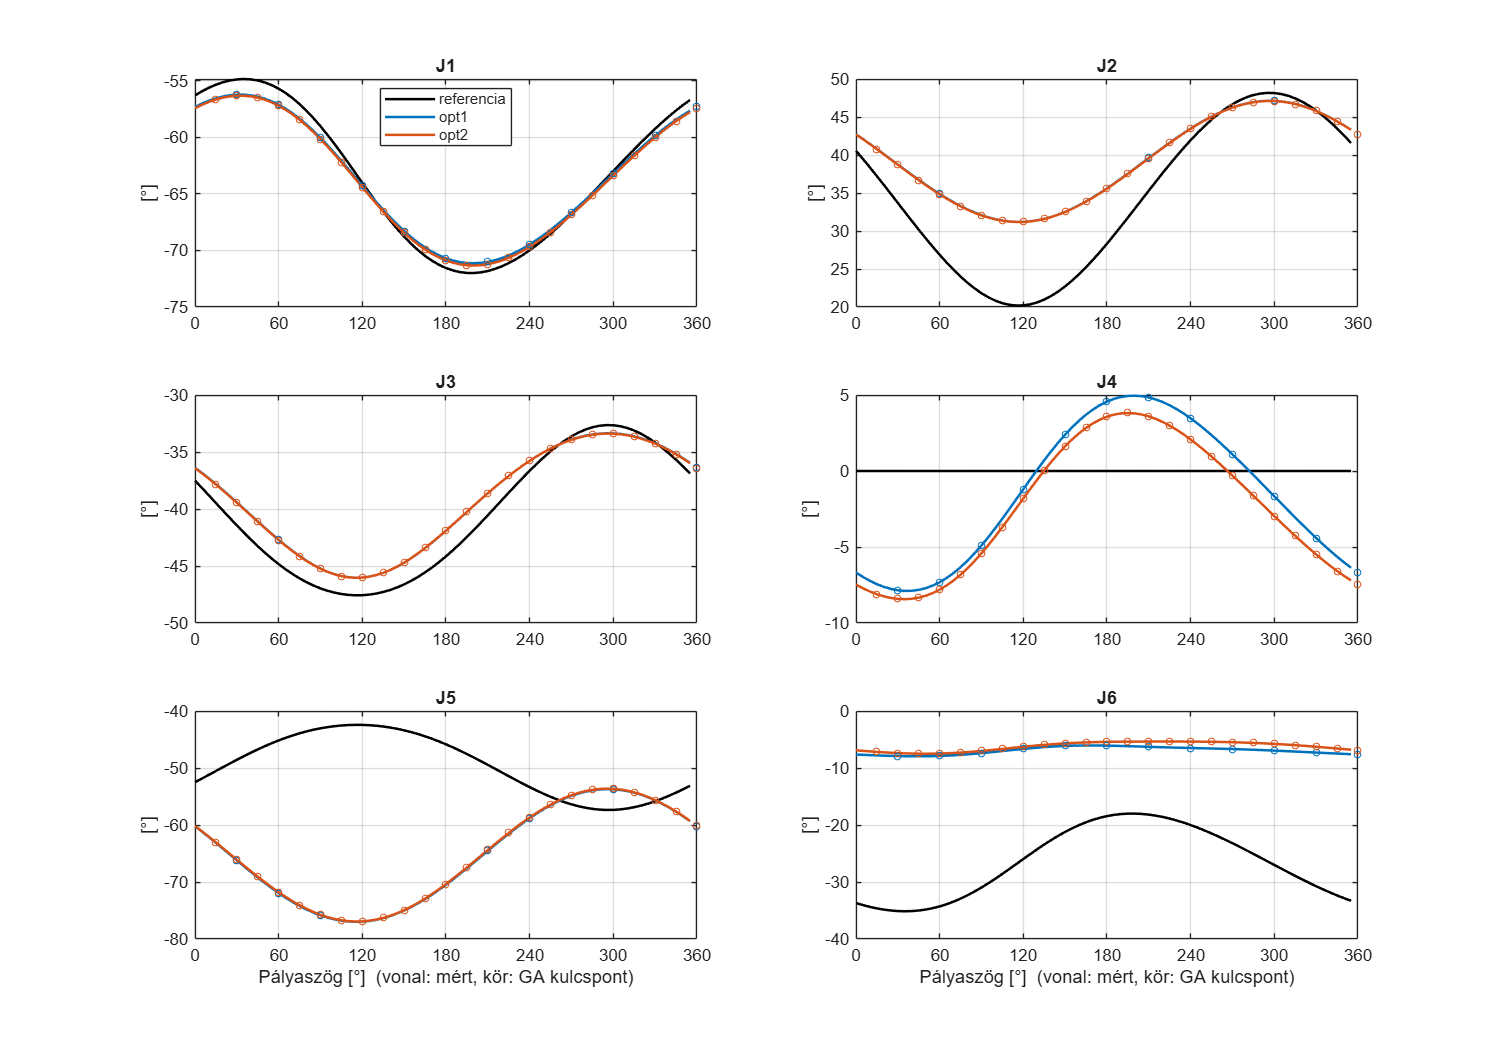


% A szektortábla CSV-be.
T2 = [];
for e = 1:ne
    for s = 1:ns
        T2 = [T2; e-1, (s-1)*szektor, s*szektor, squeeze(sek(e,s,:))', valt(e,s), elm(e,s)]; %#ok<AGROW>
    end
end
csv_iras(fullfile(out, 'szektorok.csv'), {'futas','szog_tol','szog_ig','h_d1','h_d2','h_d3','h_ossz', ...
    'mert_valt_vs_ref_pct','elmeleti_valt_vs_alap_pct'}, T2);

%% ===== Ábrák =====
% ÁBRÁK: 1. mért csuklószögek + a GA kulcsponti becslése; 2. hozzájárulás a
% kör mentén + halmozott költség; 3. szektorok (mért és elméleti);
% 4. a mért ívhossz szerinti deriváltak csuklónként.
r = '-r150';
xl = arrayfun(@(s) sprintf('%d-%d', (s-1)*szektor, s*szektor), 1:ns, 'UniformOutput', false);
szin = [0 0 0; 0 0.447 0.741; 0.85 0.325 0.098; 0.466 0.674 0.188];

% 1. csuklószögek (mért) + elméleti kulcspontok
% 1. ábra: csuklószögek.
f1 = figure('Name', 'Csuklószögek (mért)', 'Color', 'w', 'Position', [80 60 1200 850]);
for j = 1:6
    subplot(3, 2, j); hold on; grid on; box on;
    for e = 1:ne, plot(D(e).th, D(e).q(:,j), '-', 'Color', szin(e,:), 'LineWidth', 1.5); end
    for e = 2:ne
        if exist(F(e).kp, 'file')
            [K, hk] = csv_olvas(F(e).kp);
            plot(K(:,1), K(:, strcmpi(hk, sprintf('J%d', j))), 'o', 'Color', szin(e,:), 'MarkerSize', 4);
        end
    end
    xlim([0 360]); set(gca, 'XTick', 0:60:360); title(sprintf('J%d', j)); ylabel('[°]');
    if j == 1, legend(nev, 'Location', 'best'); end
    if j >= 5, xlabel('Pályaszög [°]  (vonal: mért, kör: GA kulcspont)'); end
end
print(f1, fullfile(out, 'm_1_csuklok.png'), '-dpng', r);

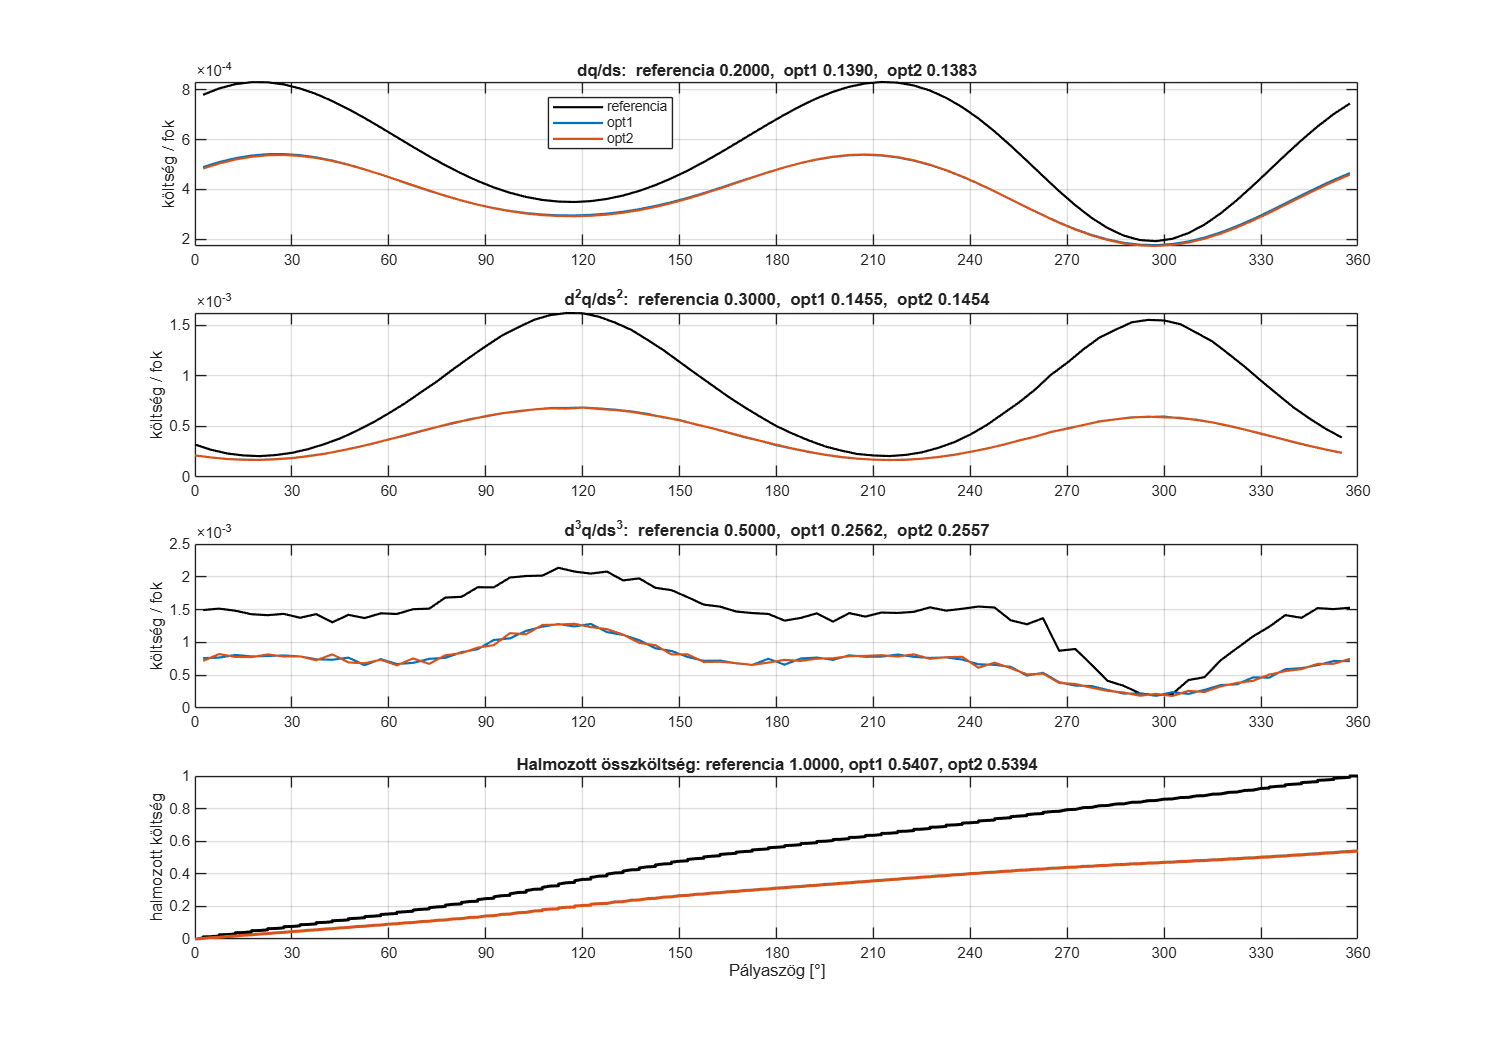


% 2. hozzájárulás a kör mentén
% 2. ábra: hozzájárulás a kör mentén.
f2 = figure('Name', 'Hozzájárulás a kör mentén (mért)', 'Color', 'w', 'Position', [80 60 1200 850]);
for k = 1:3
    subplot(4, 1, k); hold on; grid on; box on;
    for e = 1:ne
        [a, s] = sort(D(e).ang{k});
        plot(a, sum(H{e,k}(s,:), 2) / lepes, '-', 'Color', szin(e,:), 'LineWidth', 1.3);
    end
    xlim([0 360]); set(gca, 'XTick', 0:30:360); ylabel('költség / fok');
    title(sprintf('%s:  %s', mn{k}, strjoin(arrayfun(@(e) sprintf('%s %.4f', nev{e}, lam(k)*comp(k,e)), ...
        1:ne, 'UniformOutput', false), ',  ')));
    if k == 1, legend(nev, 'Location', 'best'); end
end
subplot(4, 1, 4); hold on; grid on; box on;
for e = 1:ne
    a = []; h = [];
    for k = 1:3, a = [a; D(e).ang{k}]; h = [h; sum(H{e,k}, 2)]; end %#ok<AGROW>
    [a, s] = sort(a);  cs = cumsum(h(s));
    plot([0; a; 360], [0; cs; cs(end)], '-', 'Color', szin(e,:), 'LineWidth', 1.8);
end
xlim([0 360]); set(gca, 'XTick', 0:30:360);
xlabel('Pályaszög [°]'); ylabel('halmozott költség');
title(['Halmozott összköltség: ' strjoin(arrayfun(@(e) sprintf('%s %.4f', nev{e}, J(e)), 1:ne, 'UniformOutput', false), ', ')]);
print(f2, fullfile(out, 'm_2_hozzajarulas.png'), '-dpng', r);

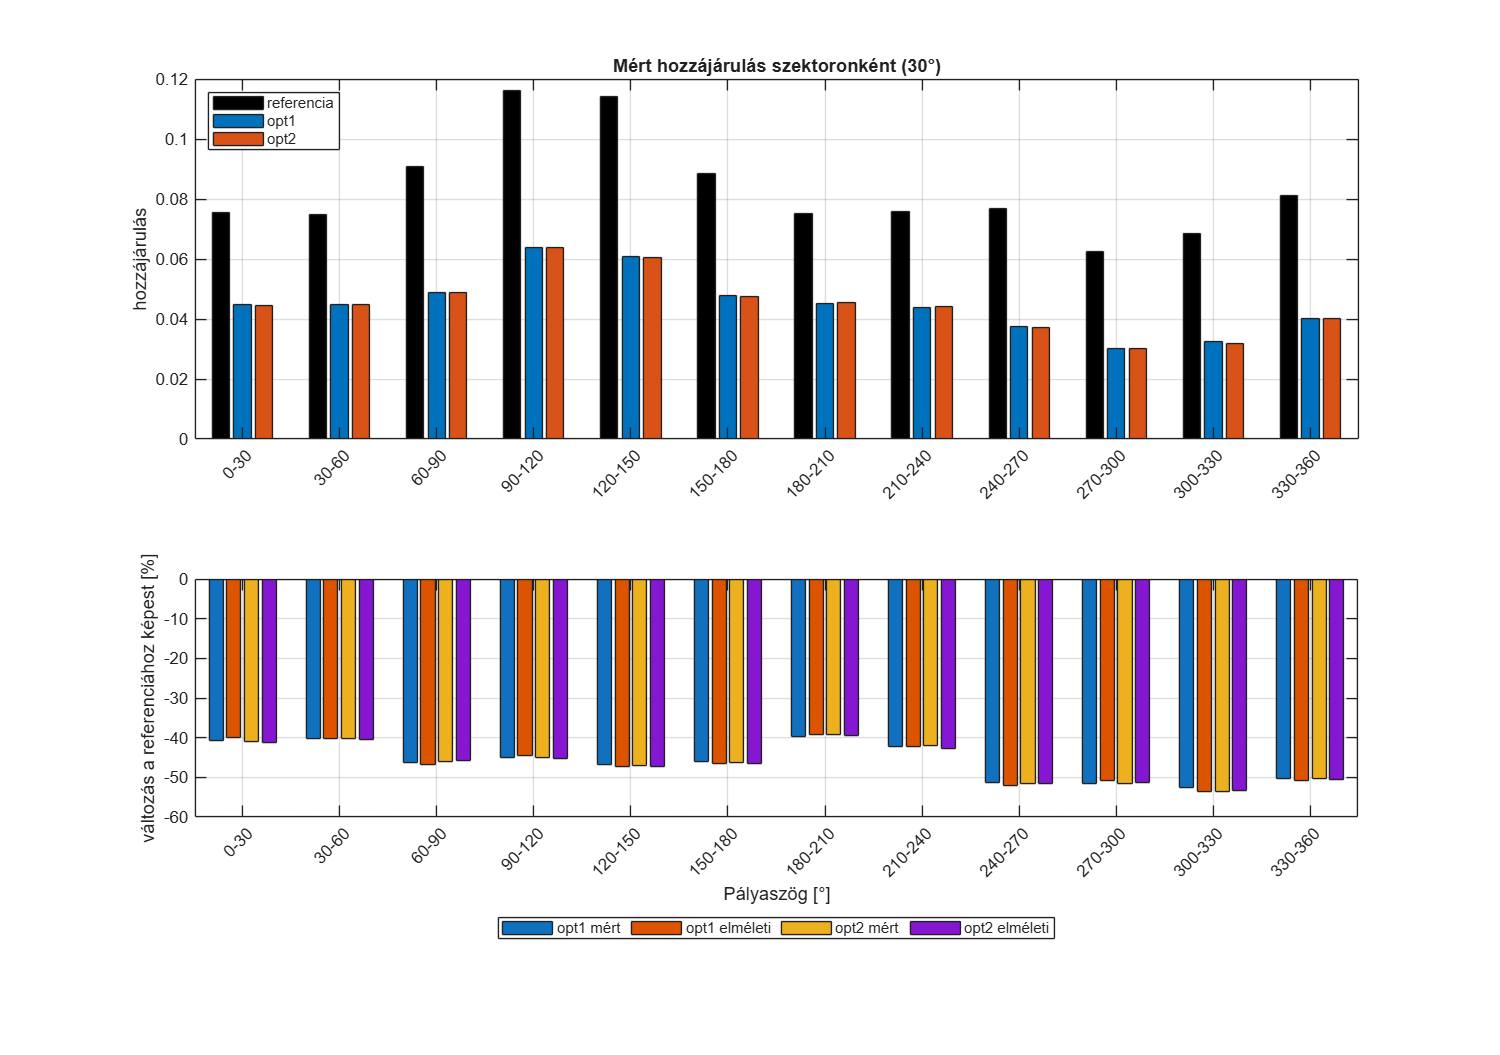


% 3. szektorok
% 3. ábra: szektorok.
f3 = figure('Name', 'Szektorok', 'Color', 'w', 'Position', [80 60 1200 850]);
subplot(2, 1, 1);
hb = bar(squeeze(sek(:,:,4))'); grid on; box on;
for e = 1:ne, set(hb(e), 'FaceColor', szin(e,:)); end
set(gca, 'XTick', 1:ns, 'XTickLabel', xl); forgat(45);
ylabel('hozzájárulás'); legend(nev, 'Location', 'northwest');
title(sprintf('Mért hozzájárulás szektoronként (%d°)', szektor));
subplot(2, 1, 2);
Y = []; lg = {};
for e = 2:ne
    Y = [Y; valt(e,:)]; lg{end+1} = sprintf('%s mért', nev{e}); %#ok<AGROW,SAGROW>
    if any(~isnan(elm(e,:))), Y = [Y; elm(e,:)]; lg{end+1} = sprintf('%s elméleti', nev{e}); end %#ok<AGROW,SAGROW>
end
bar(Y'); grid on; box on;
set(gca, 'XTick', 1:ns, 'XTickLabel', xl); forgat(45);
ylabel('változás a referenciához képest [%]'); xlabel('Pályaszög [°]');
legend(lg, 'Location', 'southoutside', 'Orientation', 'horizontal');
print(f3, fullfile(out, 'm_3_szektorok.png'), '-dpng', r);

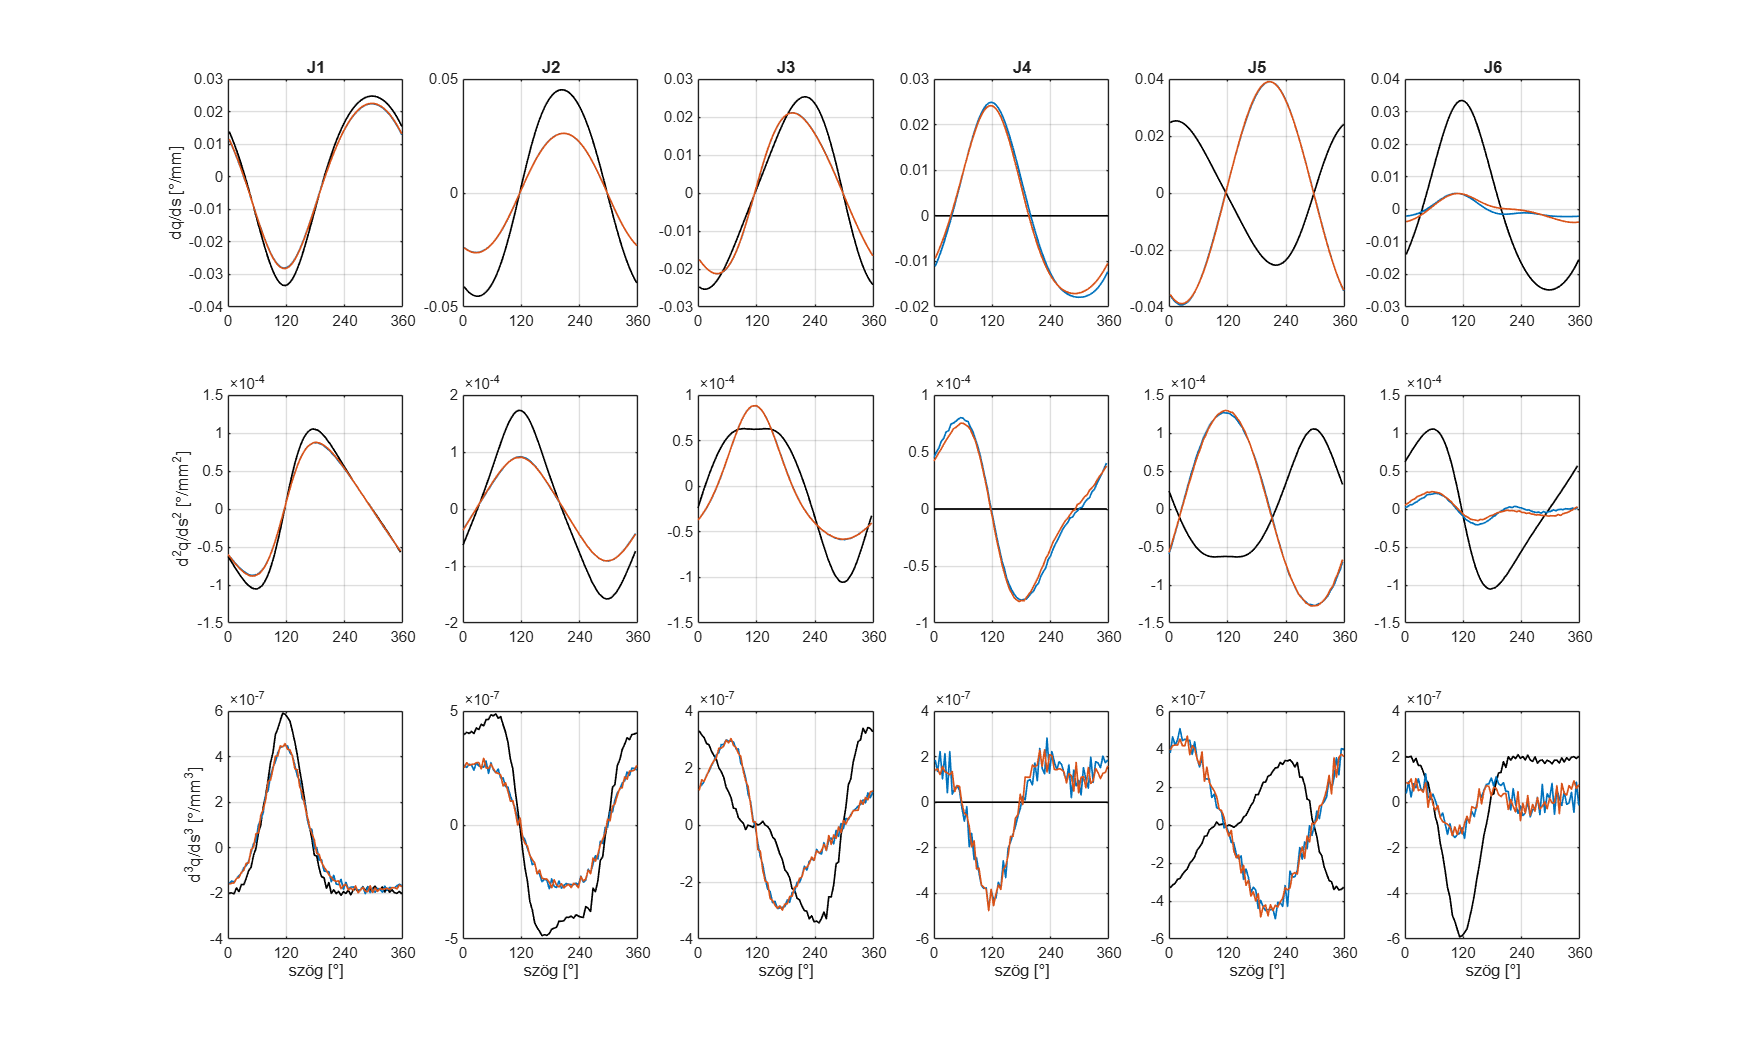


% 4. deriváltak csuklónként
% 4. ábra: deriváltak.
f4 = figure('Name', 'Ívhossz szerinti deriváltak (mért)', 'Color', 'w', 'Position', [80 60 1400 850]);
eg = {'[°/mm]', '[°/mm^2]', '[°/mm^3]'};
for k = 1:3
    for j = 1:6
        subplot(3, 6, (k-1)*6 + j); hold on; grid on; box on;
        for e = 1:ne
            [a, s] = sort(D(e).ang{k});
            plot(a, D(e).d{k}(s, j), '-', 'Color', szin(e,:), 'LineWidth', 1.0);
        end
        xlim([0 360]); set(gca, 'XTick', 0:120:360);
        if k == 1, title(sprintf('J%d', j)); end
        if j == 1, ylabel([mn{k} ' ' eg{k}]); end
        if k == 3, xlabel('szög [°]'); end
    end
end
print(f4, fullfile(out, 'm_4_derivaltak.png'), '-dpng', r);

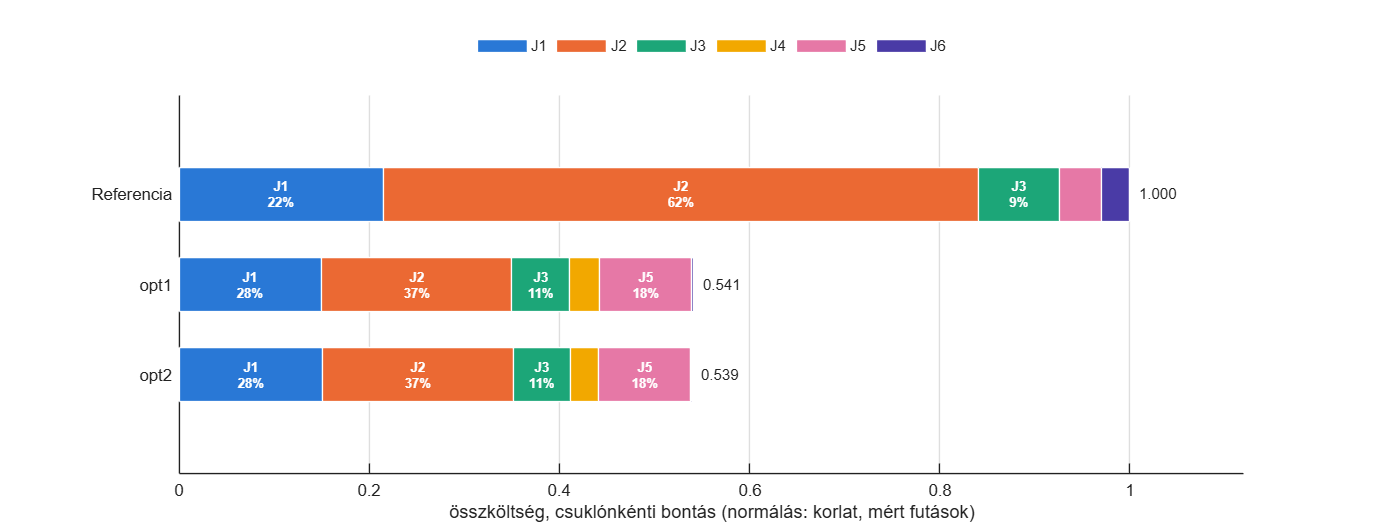


%% ===== Csuklónkénti bontás =====
% Az összköltség felbontása csuklónként: a j-edik csukló része
%   sum_d lambda_d * S(d,j) / Dn(d,j) / 6
% (ugyanaz a képlet, mint a koltseg.m-ben, csak a csuklókra nem átlagolunk).
% A hat csukló része együtt pontosan a futás összköltségét adja.
Cj = zeros(ne, 6);
for e = 1:ne
    for k = 1:3
        Cj(e, :) = Cj(e, :) + lam(k) * S(k, :, e) ./ Dn(k, :) / 6;
    end
end
% CSV: csuklónkénti rész és százalékos arány futásonként (0 = ref/Alap).
csv_iras(fullfile(out, 'hozzajarulas_csuklonkent.csv'), ...
    [{'futas'}, arrayfun(@(j) sprintf('J%d', j), 1:6, 'UniformOutput', false), {'osszesen'}, ...
     arrayfun(@(j) sprintf('J%d_pct', j), 1:6, 'UniformOutput', false)], ...
    [(0:ne-1)', Cj, sum(Cj, 2), 100 * Cj ./ repmat(sum(Cj, 2), 1, 6)]);

% Ábra: vízszintes, halmozott oszlopok futásonként (felül az Alap).
szin_j = [0.16 0.47 0.84; 0.92 0.41 0.20; 0.11 0.65 0.47; ...
          0.95 0.66 0.00; 0.90 0.47 0.65; 0.29 0.23 0.65];
cimke = nev;  cimke{1} = 'Referencia';
f8 = figure('Name', 'Csuklónkénti bontás', 'Color', 'w', 'Position', [80 60 1100 420]);
ax = axes(f8);  hold(ax, 'on');
hb = barh(ax, 1:ne, Cj, 0.6, 'stacked', 'EdgeColor', 'w');
for j = 1:6, hb(j).FaceColor = szin_j(j, :); end
% Feliratok: a széles szeletekben a csukló neve és %-a, a sor végén az összeg.
for e = 1:ne
    bal = 0;
    for j = 1:6
        w = Cj(e, j);
        if w > 0.045
            text(ax, bal + w/2, e, sprintf('J%d\n%.0f%%', j, 100*w/sum(Cj(e,:))), ...
                'HorizontalAlignment', 'center', 'Color', 'w', 'FontWeight', 'bold', 'FontSize', 8);
        end
        bal = bal + w;
    end
    text(ax, bal + 0.01, e, sprintf('%.3f', bal), 'FontSize', 9);
end
set(ax, 'YTick', 1:ne, 'YTickLabel', cimke, 'YDir', 'reverse');
xlim(ax, [0, 1.12 * max(sum(Cj, 2))]);
xlabel(ax, sprintf('összköltség, csuklónkénti bontás (normálás: %s, mért futások)', cfg.cost.norm));
legend(ax, arrayfun(@(j) sprintf('J%d', j), 1:6, 'UniformOutput', false), ...
    'Orientation', 'horizontal', 'Location', 'northoutside', 'Box', 'off');
grid(ax, 'on');  ax.YGrid = 'off';
print(f8, fullfile(out, 'm_8_csuklonkent.png'), '-dpng', r);


==================== ÍVHOSSZ vs IDŐ SZERINTI DERIVÁLÁS ====================
Pályasebesség a körön (programozott: 100 mm/s):
  futás   kör ideje   v_atl = 2*pi*R/T   v_TCP (log): átlag  szórás   min    max  [mm/s]
  referencia      20.2 s      93.46 mm/s           91.35   20.36  45.93 125.02
  opt1       20.2 s      93.51 mm/s           91.37   20.38  46.01 124.85
  opt2       20.2 s      93.48 mm/s           91.35   20.44  45.93 124.92

1) Költség, változás a ref-hez képest (ugyanaz a képlet, 72 minta a körön):
  futás   ívhossz: össz   d1      d2      d3   |  idő: össz    d1      d2      d3   | eltérés (össz)
  opt1      -45.9%   -30.5   -51.5   -48.8  |   -41.6%   -30.4   -50.9   -40.5  |  +4.3 %-pont
  opt2      -46.1%   -30.8   -51.5   -48.9  |   -41.0%   -30.8   -51.0   -39.1  |  +5.0 %-pont
  opt2 vs opt1:  ívhossz -0.24%,  idő +1.04%

2) Pontonkénti korreláció (Pearson r) az ívhossz és az idő szerinti derivált közt,
   ugyanazon a pályaszögön; skála = idő/ívhossz (legkisebb nég

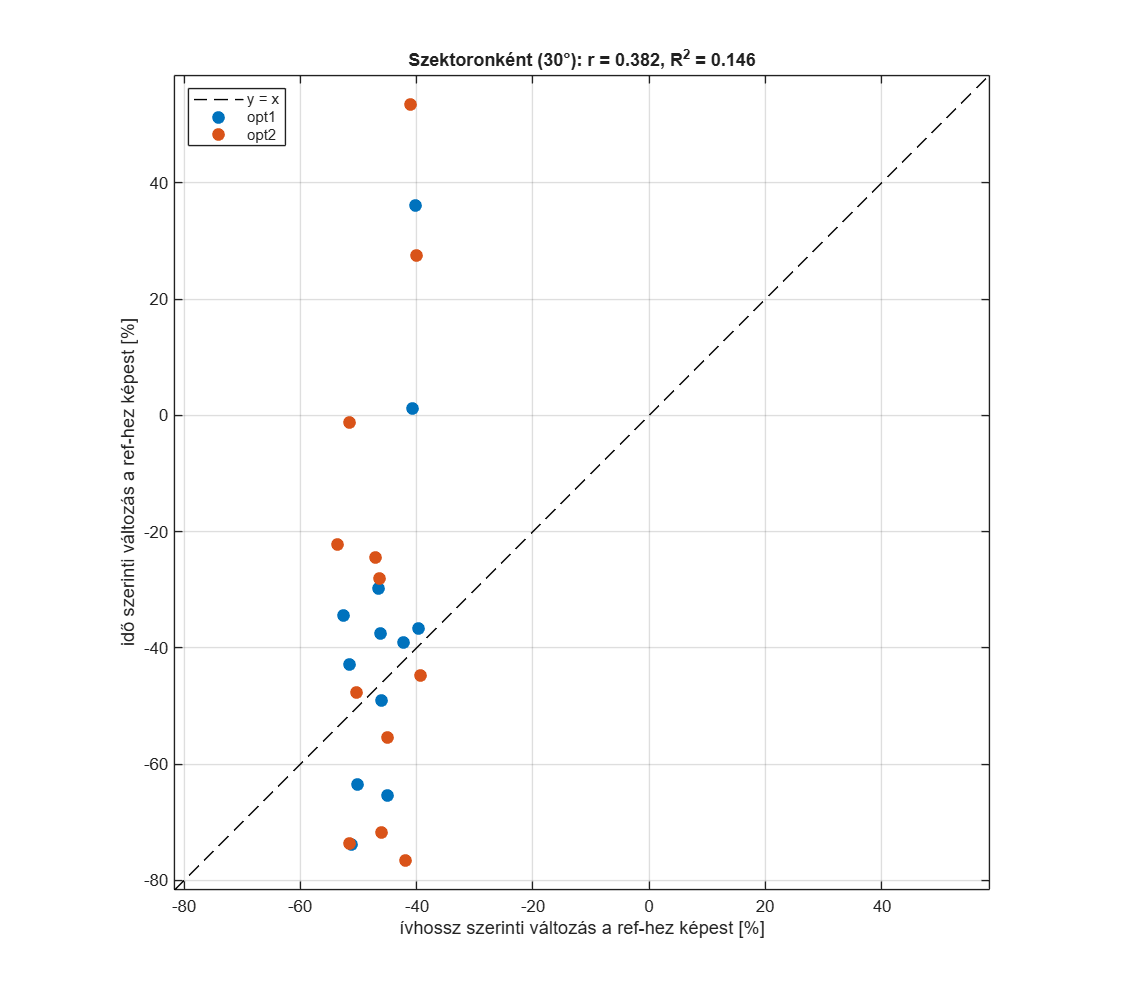

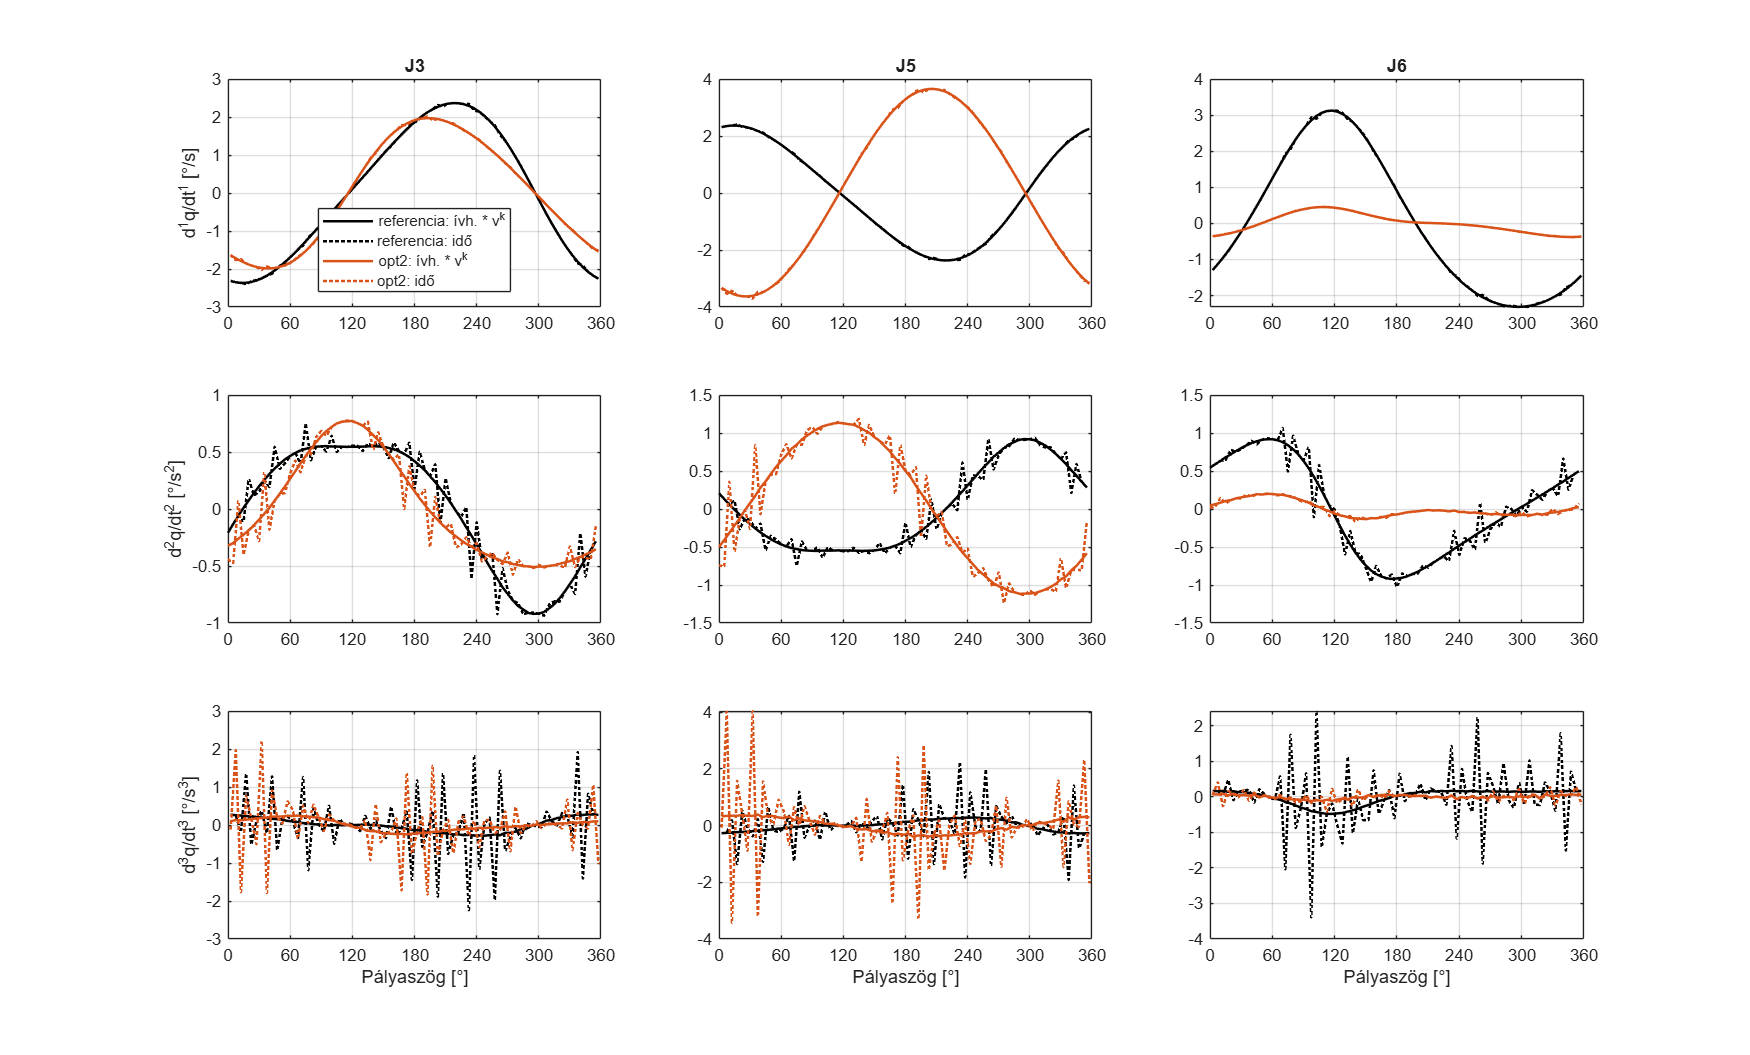


%% ===== Ívhossz vs idő szerinti deriválás (igazolás) =====
% A fő kiértékelés (fent) ívhossz szerinti, mint a GA-ban. Itt ugyanazokon a
% logokon idő szerint is deriválunk, és megnézzük, mennyire egyezik a kettő.
% Idő szerinti ellenőrzés (ido_ivhossz_vizsgalat.m).
ido_ivhossz_vizsgalat(F, D, cfg, out, lepes, szektor, kozep);


fprintf('\nKimenet: %s\n', out);


Kimenet: C:\Users\dozsa\OneDrive\Desktop\ATMENETIBME\5_felev\tdk\01_v10\04_roboguide_osszevetes\eredmenyek_korlat
